clear
addpath('..\..\utilities');

orig_mesh = 't_07_no_bl_80';
cutplane = 'XZ';
displayplots = true;

nodepos = load(fullfile('input', orig_mesh, 'Np.mat')).Np;
shearrates = load(fullfile('input', orig_mesh, 'Shearrate.mat')).SRnode;
shearrates(shearrates(:, :) == -1e+30) = 0;
temps = load(fullfile('input', orig_mesh, 'Tnode.mat')).Tnode;
temps(temps(:, :) == -1e+30) = 0;
fillstatus = load(fullfile('input', orig_mesh, 'Fillstatus.mat')).Fillstatus;
connectednodes = load(fullfile('input', orig_mesh, 'connectedNodes.mat')).connectedNodes;
connectedelements = load(fullfile('input', orig_mesh, 'connectedElements.mat')).connectedElements;
velx = load(fullfile('input', orig_mesh, 'VelX.mat')).VelX;
vely = load(fullfile('input', orig_mesh, 'VelY.mat')).VelY;
velz = load(fullfile('input', orig_mesh, 'VelZ.mat')).VelZ;
viscs = load(fullfile('input', orig_mesh, 'Visc.mat')).Visc;
viscs(viscs(:, :) == -1e+30) = 0;
% % Find the maximum value in viscs, excluding the 1000000 values
% max_viscs_excluding_1000000 = max(viscs(viscs ~= 1000000));
% % Replace the elements of viscs that have a value of 1000000
% viscs(viscs == 1000000) = max_viscs_excluding_1000000;

meshrefiner = meshRefiner;
easyvisualizer = easyVisualizer;
udmwriter = udmWriter;

% Neccesary element information for further refinement and plotting
elementnodeids = connectednodes + 1; % +1 so that indexing will work
elementnodesfilled = meshrefiner.getElementValues(elementnodeids, fillstatus);
elementfillstatus = meshrefiner.calcElementFillstatus(elementnodesfilled);
elementcoordinates = easyvisualizer.getElementCoordinates(elementnodeids, nodepos);

% Getting element values for all the investigated values
elementshearrates = meshrefiner.getElementValues(elementnodeids, shearrates);
elementtemps = meshrefiner.getElementValues(elementnodeids, temps);
[elementvellen, angle_deg] = meshrefiner.calcElementVelocities(elementnodeids, velx, vely, velz);
elementviscs = meshrefiner.getElementValues(elementnodeids, viscs);

viscdiffs_r = meshrefiner.calcElementDiffs(elementviscs, 'range');
viscdiffs_n = meshrefiner.calcElementDiffs(elementviscs, 'normrange');
viscdiffs_rr = meshrefiner.calcElementDiffs(elementviscs, 'relrange');

timestep = 30

timestep = 30

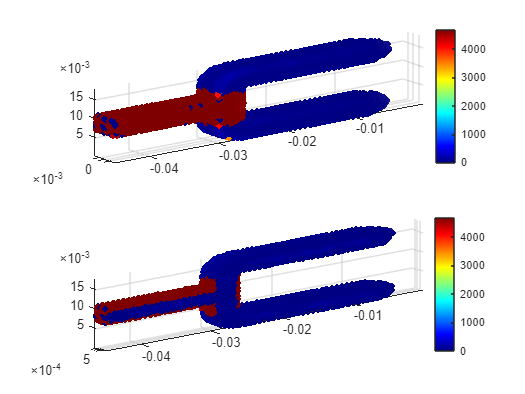


fillfig_1 = easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, viscdiffs_r, timestep, "no", true, cutplane, displayplots);

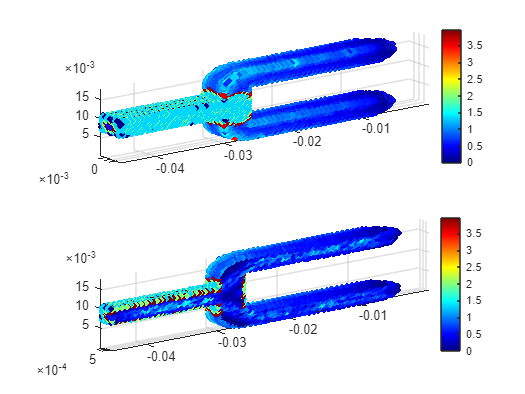

fillfig_2 = easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, viscdiffs_n, timestep, "no", true, cutplane, displayplots);

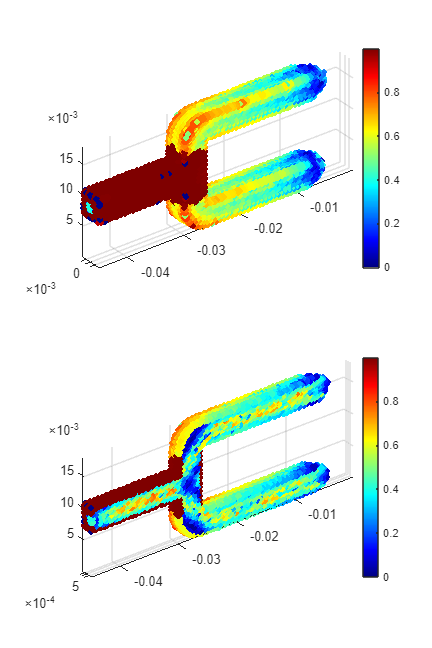

fillfig_3 = easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, viscdiffs_rr, timestep, "no", true, cutplane, displayplots);

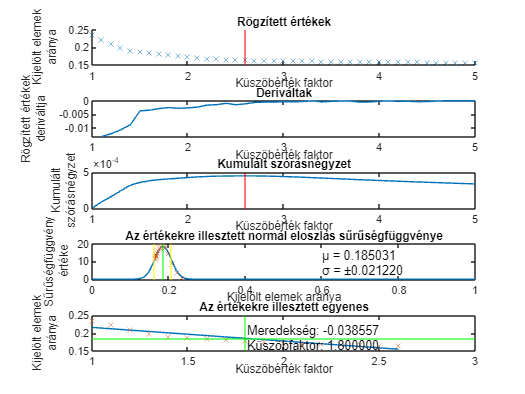

% viscs
[highviscdiffs_r, normalviscdiffs_r, highviscdiffsbytimestep_r, ideal_threshold_visc_r, slope_visc_r, s_visc_r, frac_visc_r, ctpn_visc_r, fig_visc_r] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, viscdiffs_r, true, true, displayplots, 0.1, 10);

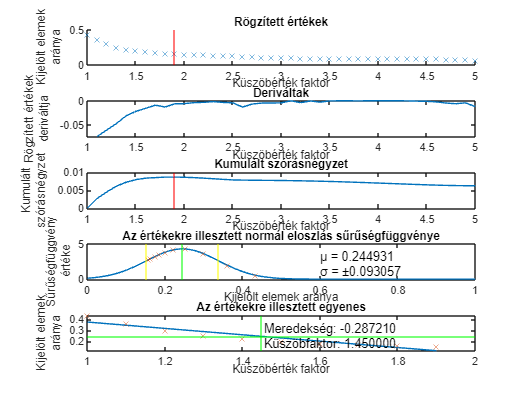



[highviscdiffs_n, normalviscdiffs_n, highviscdiffsbytimestep_n, ideal_threshold_visc_n, slope_visc_n, s_visc_n, frac_visc_n, ctpn_visc_n, fig_visc_n] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, viscdiffs_n, true, true, displayplots, 0.1, 10);

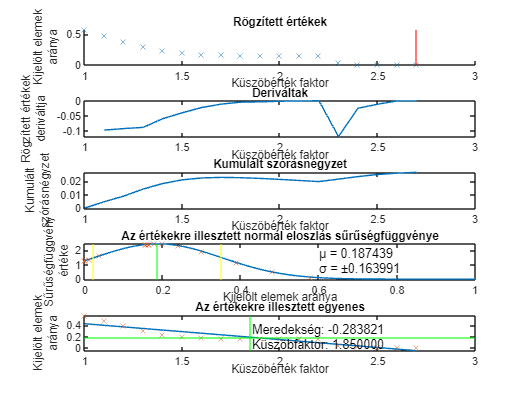



[highviscdiffs_rr, normalviscdiffs_rr, highviscdiffsbytimestep_rr, ideal_threshold_visc_rr, slope_visc_rr, s_visc_rr, frac_visc_rr, ctpn_visc_rr, fig_visc_rr] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, viscdiffs_rr, true, true, displayplots, 0.1, 10);

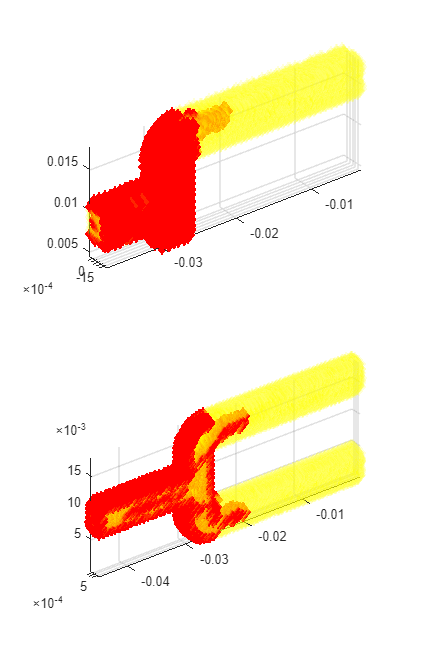

elemfig_visc_r = easyvisualizer.plotElementsToRefine(elementcoordinates, highviscdiffs_r, normalviscdiffs_r, 0, cutplane, displayplots);

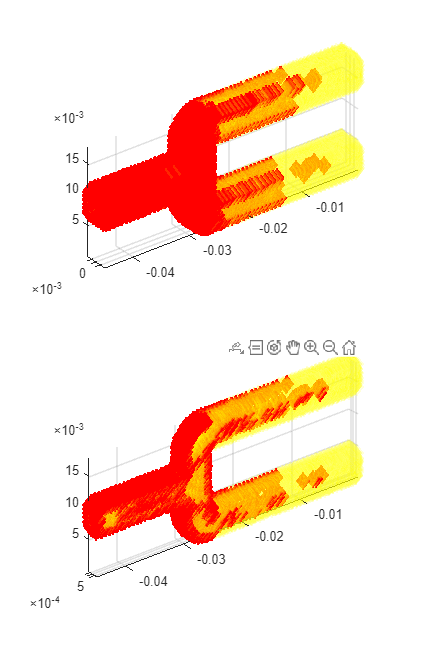

elemfig_visc_n = easyvisualizer.plotElementsToRefine(elementcoordinates, highviscdiffs_n, normalviscdiffs_n, 0, cutplane, displayplots);

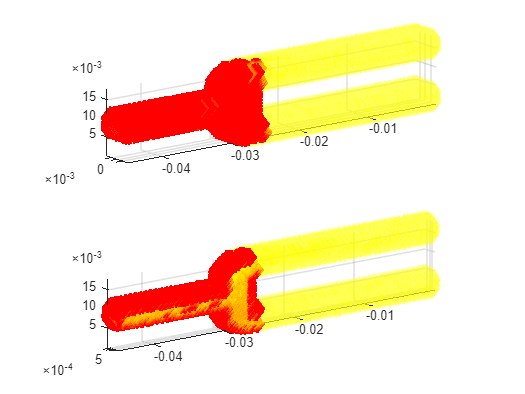

elemfig_visc_rr = easyvisualizer.plotElementsToRefine(elementcoordinates, highviscdiffs_rr, normalviscdiffs_rr, 0, cutplane, displayplots);